# Exercise 14

clc;
close all;
clear variables;

set(groot, 'defaulttextinterpreter', 'latex');  
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');  
set(groot, 'defaultLegendInterpreter', 'latex');

Subscript : $\big(a - acceleration, p - plateau, d - deceleration, i - initial, f - final, t - total\big)$

## Task 1

### a) 

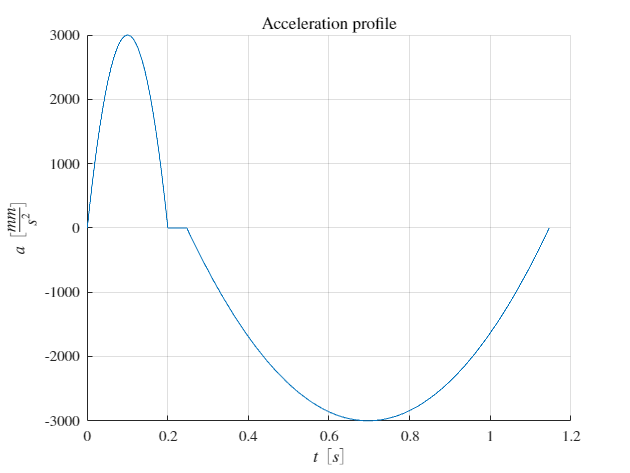

syms a_a(t) a_p(t) a_d(t)
syms p_a p_d [3, 1]

a_max = 3000; % mm/s^2

v_i = 1400; % mm/s
v_f = 0;
v_max = 1800; % mm/s

syms t_a t_p t_d

t_p = 0.047;

a_a(t) = t.^(0:2) * p_a;
a_p(t) = sym(0);
a_d(t) = t.^(0:2) * p_d;

conds_a = [a_a(0) == 0; 
          a_a(t_a/2) == a_max;
          subs(diff(a_a, t), t, t_a/2) == 0;
          int(a_a, t, 0, t_a) == v_max - v_i];

sol_a = solve(conds_a, [p_a; t_a]);
sol_a_mat = struct2mat(sol_a);

conds_d = [a_d(0) == 0; 
          a_d(t_d/2) == -a_max;
          subs(diff(a_d, t), t, t_d/2) == 0;
          int(a_d, t, 0, t_d) == v_f - v_max];

sol_d = solve(conds_d, [p_d; t_d]);
sol_d_mat = struct2mat(sol_d);

a_a_sol = subs(a_a, p_a,sol_a_mat(1:3));
a_d_sol = subs(a_d, p_d,sol_d_mat(1:3));

a = a_a_sol(t) * (heaviside(t) - heaviside(t - sol_a.t_a)) + ... 
    a_d_sol(t - t_p - sol_a.t_a) * (heaviside(t - sol_a.t_a - t_p) - heaviside(t - sol_a.t_a - t_p - sol_d.t_d));

figure
hold on
grid on
color = '#0072BD';
fplot(a, [0 double(vpa(sol_a.t_a + t_p + sol_d.t_d))], 'Color', color)
title('Acceleration profile')
xlabel('$t \ [s]$')
ylabel('$a \ [\frac{mm}{s^2}]$')

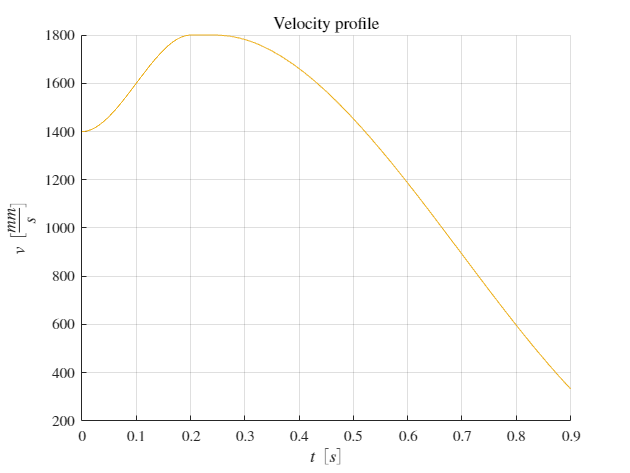

v = v_i + int(a, t);
figure
hold on
grid on
color = '#EDB120';
fplot(v, [0 double(vpa(sol_d.t_d))], 'Color', color)
title('Velocity profile')
xlabel('$t \ [s]$')
ylabel('$v \ [\frac{mm}{s}]$')

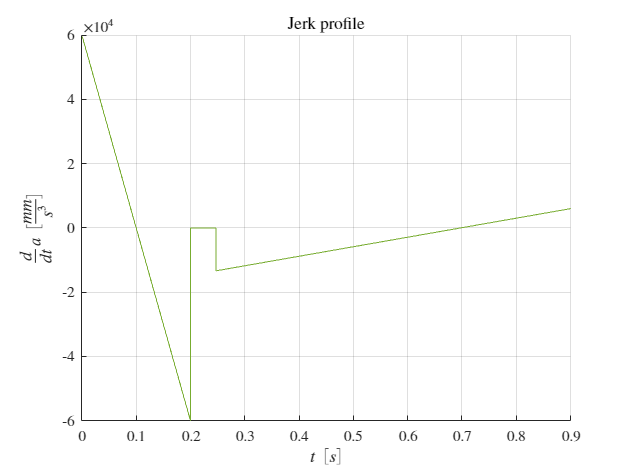

jerk = diff(a, t);
figure
hold on
grid on
color = '#77AC30';
fplot(jerk, [0 double(vpa(sol_d.t_d))], 'Color', color)
title('Jerk profile')
xlabel('$t \ [s]$')
ylabel('$\frac{d}{dt}a \ [\frac{mm}{s^3}]$')

### b) c) d) e)

p_i = [-520; 215; -30]; % mm
p_f = [580;  575; 340]; % mm
u = symunit; % units for display
dist = round(vpa(sym(norm(p_i - p_f))), 1) * u.mm

$$dist = 1215.1\,\mathrm{mm}$$

v_a = int(a_a, t, 0, t) + v_i

$$v\_a = \frac{p_{\mathrm{a3}}\,t^{3}}{3}+\frac{p_{\mathrm{a2}}\,t^{2}}{2}+p_{\mathrm{a1}}\,t+1400$$

s_a = int(v_a, 0, sol_a.t_a);
s_a = subs(s_a, p_a, sol_a_mat(1:3)) * u.mm

$$s\_a = 320\,\mathrm{mm}$$

v_d = v_max + int(a_d_sol, t, 0, t);
s_d = int(v_d, 0, sol_d.t_d);
sold_subs = struct2mat(sol_d);
s_d = round(vpa(subs(s_d, p_d, sold_subs(1:3))), 2) * u.mm

$$s\_d = 810.0\,\mathrm{mm}$$

The discrepancy between the solution in the pdf - $814 mm$ and mine bugs me.

sp = vpa(dist - s_d - s_a)

$$sp = 85.1\,\mathrm{mm}$$

t_p = vpa(sp / v_max / u.mm * u.s, 3)

$$t\_p = 0.0473\,s$$

## Task 2

clear variables
a_max = 100; % rad/s^2
t_t = 0.5; % s
phi_t = 3; % rad
omega_i = 0; % rad/s
omega_f = 0; % rad/s

### a) b)

syms t t_a omega_max
assume(omega_max, 'positive')
syms p_a [3 1]
a_a(t) = t.^(0:2) * p_a

$$a\_a(t) = p_{\mathrm{a3}}\,t^{2}+p_{\mathrm{a2}}\,t+p_{\mathrm{a1}}$$

omega_a(t) = omega_i + int(a_a, t, 0, t)

$$omega\_a(t) = \frac{p_{\mathrm{a3}}\,t^{3}}{3}+\frac{p_{\mathrm{a2}}\,t^{2}}{2}+p_{\mathrm{a1}}\,t$$

Calculating $p_a$


% parabolic a profile conditions
conds_a = [a_a(0) == 0;
           a_a(t_a / 2) == a_max;
           subs(diff(a_a), t, t_a / 2) == 0;
           omega_a(t_a) == omega_max];
sol_a = solve(conds_a, [p_a; t_a])

sol_a = struct with fields:
    p_a1: 0
    p_a2: 80000/(3*omega_max)
    p_a3: -16000000/(9*omega_max^2)
     t_a: (3*omega_max)/200


sol_a_mat = struct2mat(sol_a);
omega_a = subs(omega_a, p_a, sol_a_mat(1:3))

$$omega\_a(t) = \frac{40000\,t^{2}}{3\,\omega_{\max}}-\frac{16000000\,t^{3}}{27\,{\omega_{\max}}^{2}}$$

t_a = sol_a.t_a

$$t\_a = \frac{3\,\omega_{\max}}{200}$$

### c)

phi_a = int(omega_a, t, 0, t_a)

$$phi\_a = \frac{3\,{\omega_{\max}}^{2}}{400}$$

### d)

t_d = t_a

$$t\_d = \frac{3\,\omega_{\max}}{200}$$

t_p = t_t - t_d - t_a

$$t\_p = \frac{1}{2}-\frac{3\,\omega_{\max}}{100}$$

### e)

phi_p = int(omega_max, t, 0, t_p)

$$phi\_p = -\frac{\omega_{\max}\,\left(3\,\omega_{\max}-50\right)}{100}$$

phi_d = phi_a;
sol_omega_max = solve(phi_a + phi_p + phi_d == phi_t, omega_max)

$$sol\_omega\_max = \left(\begin{array}{c} \frac{50}{3}-\frac{10\,\sqrt{7}}{3}\\ \frac{10\,\sqrt{7}}{3}+\frac{50}{3} \end{array}\right)$$

sol_index = 2;
sol_t_p_invalid = vpa(subs(t_p, omega_max, sol_omega_max(2)))

$$sol\_t\_p\_invalid = -0.26457513110645905905016157536393$$

sol_t_p_valid = vpa(subs(t_p, omega_max, sol_omega_max(1)))

$$sol\_t\_p\_valid = 0.26457513110645905905016157536393$$

Of the 2 solutions one yields a negative $t_p$ so we chose the other one

omega_max = round(vpa(sol_omega_max(1)), 3)

$$omega\_max = 7.847$$

function mat_params = struct2mat(struct_params)
    cell_params = struct2cell(struct_params);
    mat_params = [cell_params{:}]';
end